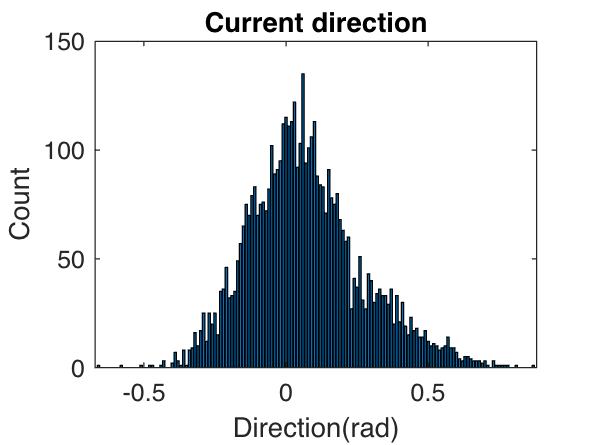



[a4,b4,c4]=size(DEN);
D=zeros(12*a4,b4);
for i=1:12:c4
    %every month 
    M4=[squeeze(DEN(:,:,i));
        squeeze(DEN(:,:,i+1));
        squeeze(DEN(:,:,i+2));
        squeeze(DEN(:,:,i+3));
        squeeze(DEN(:,:,i+4));
        squeeze(DEN(:,:,i+5));
        squeeze(DEN(:,:,i+6));
        squeeze(DEN(:,:,i+7));
        squeeze(DEN(:,:,i+8));
        squeeze(DEN(:,:,i+9));
        squeeze(DEN(:,:,i+10));
        squeeze(DEN(:,:,i+11)) ]; 
    D=M4./(c4/12)+D; % every month average angle to north
end

DD=[];%zeros(12*a4*b4,1);
for jj=1:b4
    DD=[DD;D(:,jj)];
end

Dcc = roundn(DD,-2);
tbl4 = tabulate(Dcc);%统计数组x中元素出现的频率
t4 = array2table(tbl4, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表

% subplot(224)
bar(t4.Value,t4.Count);
xlabel("Direction(rad)");
ylabel("Count")
title("Current direction")

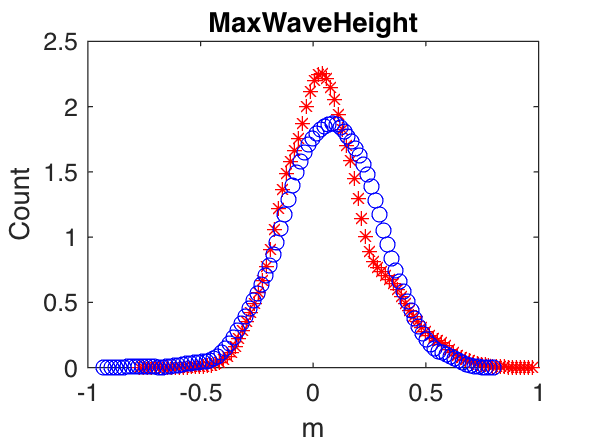


%MH=app.Wave_MH;
[mu,sigma]= normfit(DD,0.05);
TJ=ones(1000,1);
LTJ=length(TJ);
DD1=normrnd(mu,sigma,1,LTJ);

[f,xi]=ksdensity(DD);
% app.Original_TypicalPanel.AutoResizeChildren = 'off';
ax1 = [];%subplot(1,3,1,'Parent',app.Original_TypicalPanel);
plot(xi,f,'r*');
xlabel("m");
ylabel("Count")
title("MaxWaveHeight")    
hold('on');
[f1,xi1]=ksdensity(DD1);
plot(xi1,f1,'bo');
hold('off');